# Robust Video Stabilization with Template Matching 

In this example, you'll apply a more robust approach of template matching to compensate for camera motion. Specifically, you'll update the template and ROI at each frame in the video. Updating the template image and ROI helps account for motion in the z-direction and effects due to changes in lighting. 

We recommend working through the simple version first if you haven't already. That way you'll be familiar with the overall workflow before adding the additional code to update the template and ROI. 

Work through the script section by section and examine the code. Ask us questions on the discussion forums if you have questions about what a section of code is doing.

### Faster Performance Using an ROI

You should notice that this script executes much faster compared to the simple version, even though this approach has extra code to update the template and search ROI. That is because using an ROI means the template matching algorithm will only run on a small part of the image, greatly improving algorithm performance. Even if you don't need to update the template image or ROI for your application, you should consider using an ROI for performance.

**Note**: Running this script will write new video files to your current folder location.

## Initialization 

Here, the initialization is very similar to that of the simple case. The main difference is that you need to define an ROI.

### Create Video Reader and Writer Objects

Run this section to create a `VideoReader` object for the shaky video and a `VideoWriter` object for the stabilized video.

shakyV = VideoReader("ShakyStreet.avi");
stableV = VideoWriter("robustStabilizedVideo.avi");

### Create the Template Image and ROI

A good template should be distinct and, ideally, unique in the video. It also helps if the template has sharp edges with large changes in pixel values. Misaligning a sharp edge will result in a large SSD value, reducing the chances of an incorrect match.

Read in the first frame of the video. Inspect the image in the Image Viewer app or in a figure window.  

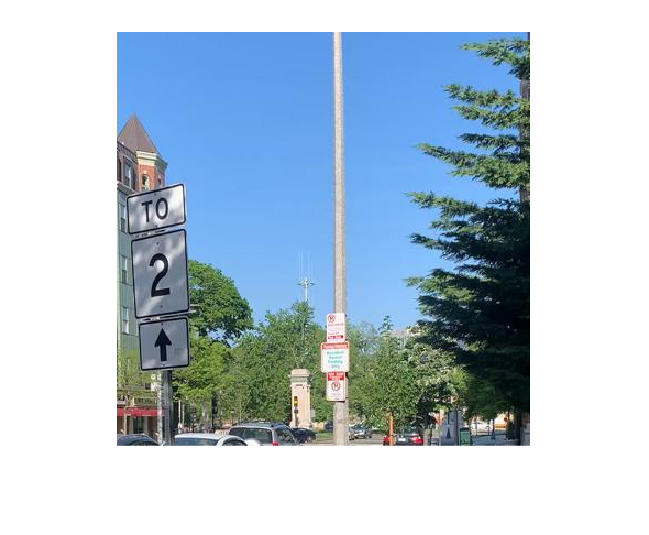

frame1 = read(shakyV,1);
imshow(frame1)

#### Create the initial Template

From inspection, the upper-right corner of the sign that says "To" is located at `[x, y] = [60 140]`. You need to crop a small region of the image centered at this location to use as a template. The `imcrop` function will crop a region using a 4-element vector `[xmin, ymin, width, height]`. For this video and resolution, a 20-by-20 pixel template is appropriate. 

Run this section to create the template image.

templateOrigin = [60 140];
wT = 20;
hT = 20; 
xmin = templateOrigin(1) - round(wT/2);
ymin = templateOrigin(2) - round(hT/2);
template = imcrop(frame1,[xmin, ymin, wT, hT]);

Template matching is performed using grayscale images, so convert the template to grayscale.

template = im2gray(template);

#### Create the initial ROI

Center the initial ROI at the template origin and use a 50-by-50 pixel region. Remember that the ROI should be defined as a 4-element vector `[xmin, ymin, width, height].`

Run this section to create the initial ROI.

wROI = 50;
hROI = 50;
xminROI = templateOrigin(1) - round(wROI/2);
yminROI = templateOrigin(2) - round(hROI/2);
searchROI = [xminROI, yminROI, wROI, hROI];

templateOrigin

templateOrigin =     60   140


searchROI

searchROI =     35   115    50    50


[xmin, ymin, wT, hT]

ans =     50   130    20    20


View the template and the original image with a box of the template location.

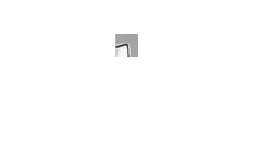

imshow(template)

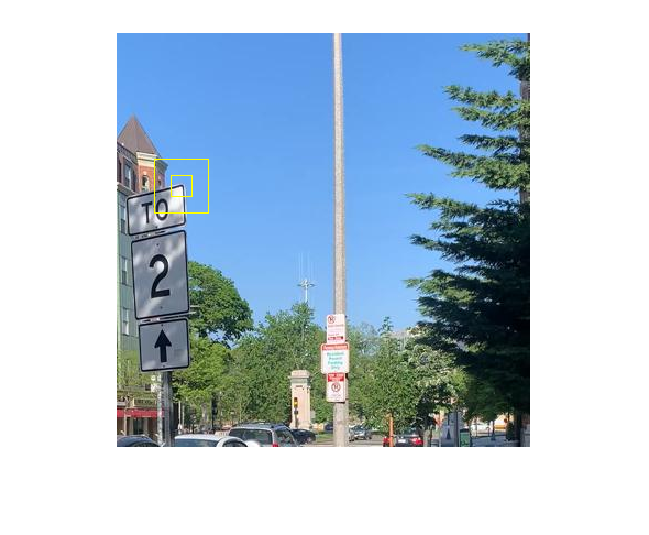

frame1 = insertShape(frame1,"Rectangle",[xmin, ymin, wT, hT]);
frame1 = insertShape(frame1,"Rectangle",[xminROI, yminROI, wROI, hROI]);
imshow(frame1)

This should be a good template. There are distinct edges, a corner, and bright pixels inside the sign and darker gray pixels outside the sign. 

## Stabilize the Video

Run this section to create a stabilized video. **This may take a minute or two to run and will write a file to your computer.** 

Loop through the frames in the video and:

- find the template position

- calculate the offset compared to the reference frame (this is the same as the cumulative motion)

- translate the frame to correct for motion

- write the corrected frame to the `VideoWriter` object

#### Max and Min Offsets

While not necessary, you may want to crop the video to include only the pixels that appear in every frame as you saw in the lesson. To do this, you need to keep track of the maximum and minimum offset translations in the x and y-directions for cropping after stabilization.

xMinOffset = 0;
xMaxOffset = 0;
yMinOffset = 0;
yMaxOffset = 0;

### Create the Template Matcher

Create the `TemplateMatcher` object. Specify that an ROI will be used to limit the search area.

templateMatcher = vision.TemplateMatcher("ROIInputPort",true);

### Loop Through Video

This is similar to the simple case, but there are three main changes:

- Update the Template every frame

- Update the ROI every frame

- Calculate the cumulative offset of the template from frame 1

In the simple version you saw previously the template position did not change. Therefore, the total offset was just the current position of the template minus the starting template position. Now, you must initialize an offset and previous template position and update these values each time through the loop.

offset = [0 0];
prevTemplatePos = templateOrigin;

Open the VideoWriter object for writing

open(stableV)

Get the number of frames and loop through the video.

nFrames = shakyV.NumFrames;
for ii = 1:nFrames
    currFrameColor = read(shakyV,ii);

    % Convert to grayscale for template matching
    currFrameGray = im2gray(currFrameColor);

    % Find the position of the template in the frame
    % Template matching is optimized for data type double, so convert the
    % inputs.
    currFrameGray = im2double(currFrameGray);
    template = im2double(template);
    templatePos = templateMatcher(currFrameGray,template,searchROI);

    % templatePos is of data type int32
    % Convert to double to subtract the previous template position to get
    % the motion between frames
    templatePos = double(templatePos);
    displacement = templatePos - templateOrigin;

    % Add the displacement to the total offset
    offset = offset + displacement;

    % Translate the color frame by the negative of the offset
    stabilizedFrame = imtranslate(currFrameColor,-offset);

    % Write the video
    writeVideo(stableV,stabilizedFrame);    

**Update the template and the ROI for the next iteration**

    % Update the origin and crop a new template from the current frame
    templateOrigin = templatePos;
    xmin = templateOrigin(1) - round(wT/2);
    ymin = templateOrigin(2) - round(hT/2);
    template = imcrop(currFrameGray,[xmin, ymin, wT, hT]);

    % Update the search ROI
    searchROIOrigin = templateOrigin;
    xminROI = templateOrigin(1) - round(wROI/2);
    yminROI = templateOrigin(2) - round(hROI/2);
    searchROI = [xminROI, yminROI, wROI, hROI];

The rest of the loop is for keeping track of the maximum offsets of the template as it moves throughout the video. This may or may not be necessary depending on your application. These values are used in the next code section to crop the video.

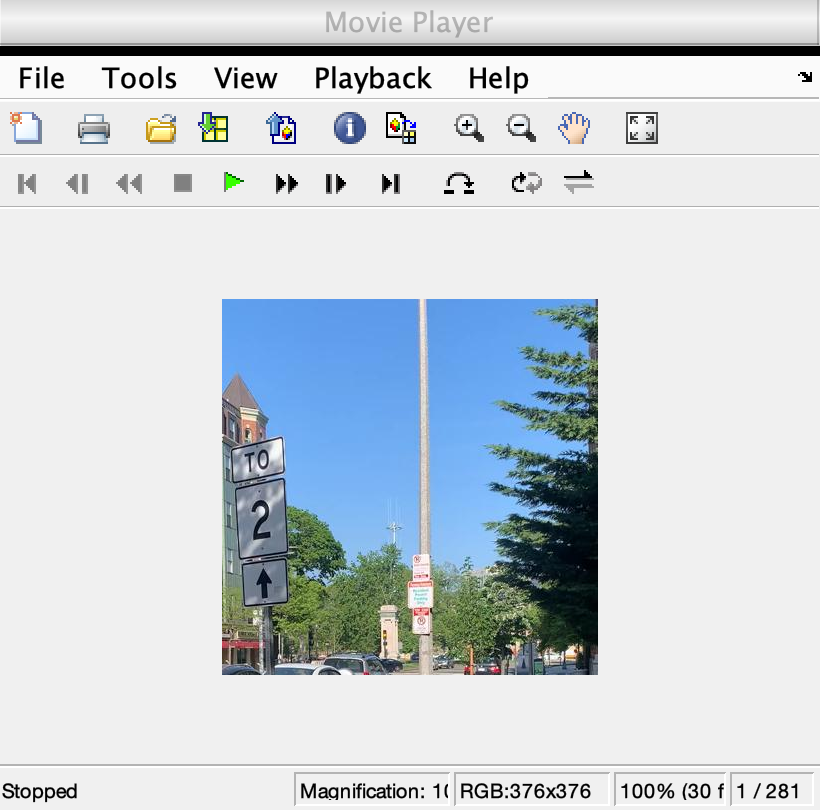

    % Check if the x and y offsets are larger or smaller than the current offset values. 
    % If so, update the current values to the new min/max.
    if offset(1) < xMinOffset
        xMinOffset = offset(1);
    end

    if offset(1) > xMaxOffset
        xMaxOffset = offset(1);
    end

    if offset(2) < yMinOffset
        yMinOffset = offset(2);
    end

    if offset(2) > yMaxOffset
        yMaxOffset = offset(2);
    end

    
end

Close the VideoWriter object

close(stableV)

## Post Processing

Use the offsets to crop the edges of the video so that only the pixel ranges that appear in all frames are included in the final video. To do this, you need the number of rows and columns of the image. 

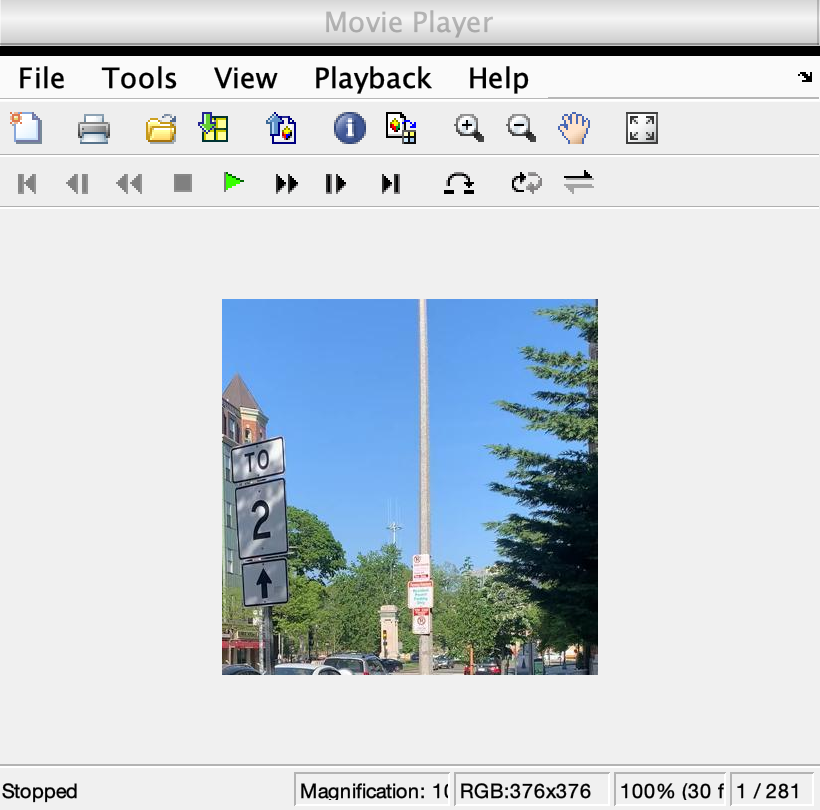

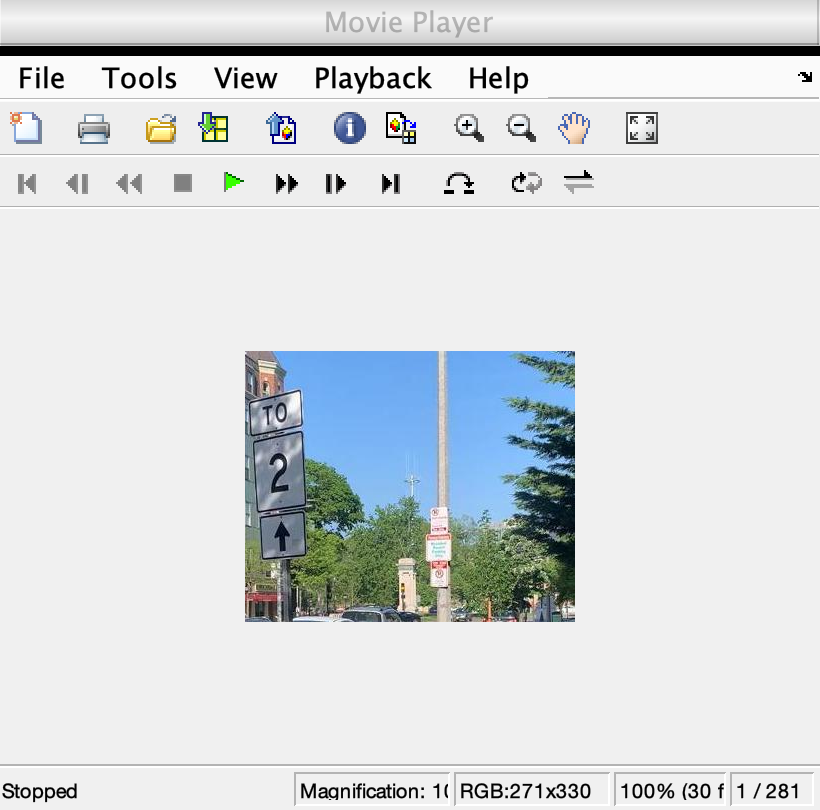

nrows = size(frame1, 1);

ncols = size(frame1, 2);

The x and y minimum offsets are either negative or 0. Therefore, the starting column and row indices will be the offsets + 1. Similarly, you must subtract off the x and y max offsets. 

#### Create vectors of row and column indices that are in every frame

rowIndices = abs(yMinOffset) + 1:nrows - yMaxOffset;
colIndices = abs(xMinOffset) + 1:ncols - xMaxOffset;

### Create the cropped video

This time, use the stabilized video as the initial video. Extract from each frame only the rows and columns that are in every frame.

newV = VideoReader("robustStabilizedVideo.avi");
vCropped = VideoWriter("robustStabilizedVideoCropped.avi");
open(vCropped)
nFrames = newV.NumFrames; 

for jj = 1:nFrames
    frame = read(newV,jj);
    % Extract only the rows and columns that appear in every frame
    frame = frame(rowIndices,colIndices,:);

    % Write the new image to the cropped video
    writeVideo(vCropped,frame)
end
close(vCropped)

implay("ShakyStreet.avi")
figure
implay("robustStabilizedVideo.avi")
figure
implay("robustStabilizedVideoCropped.avi")

*Copyright 2022 The MathWorks, Inc.*